# ME: 6240 Long Homework 3

Particle Filter Localization

4-12-2021

## Michael Swafford

#### Consider the same airplane from SHW 4 that can only move in one dimension (forward and backward), and assume it is moving in the forward direction at a known constant velocity. We will start with the same prior belief for the location of the airplane,

## 
$$bel(x)=\frac{1}{5.75}exp(\frac{-x^2}{2})[sin^2(x+6)+3cos^2(x)sin^2(4x)+1]$$


#### with the same base of support $\in [-4,4]$. This airplane will have the same process model that you will use to propagate the particles over a time step, $\delta t$, per,

## 
$$x_{k+1} = x_k + s_0\delta t+w_k$$


#### where $s_0 = 10 m/s,\delta t = 0.05 sec,$and $w_k \sim \mathcal{N}(0,2)$. As before, for every time step, you will need to generate a new vector, $w_k \in \mathbb{R}^N$, from the normal distribution governing the process noise. For this homework, use N = 1000 particles.

#### The extension for this homework is we now have a map of the area that the airplane is operating in, which spans $\in [-100m,100m]$. Instead of a landmarks-based map, this map is a continuous representation of the topography of the terrain. The provided **top_map function provides the elevation of the terrain relative to sea level for a given x-coordinate (i.e., z = top_map(x)). Note that if you input an x-coordinate that is outside of the domain of the map (**$-100\leq x \leq 100$), then the function returns NaN. Since we are assuming the airplane remains within the domain of the map, you can assume that the probability of any particles outside of the domain is 0.

#### One of the sensors on the airplane is an absolute altimeter, which provides the altidude of the airplane relative to sea level. The measurement noise for this sensor follows a normal distribution, $v_{abs}\sim \mathcal{N}(0,1.5)$. The other sensor on the plane is a relative altimeter, which provides the altitude of the airplane relative to the terrain directly below it. The measurement noise for this sensor follows a normal distribution, $v_{rel}\sim \mathcal{N}(0,2)$. Both sensors are sampling simultaneously at 0.5 Hz. The MATLAB data file contains a variable z for which the first column contains the times when the measurements were made, the second column contains the absolute altitude measurements, and the third column contains the relative altidue measurements. Assume that we only have 8 seconds of data (i.e., only propagate the particels for 8 seconds).

# 1) **Provide a plot of the map using the top_map function provided and knowledge of the domain of the map.** **Now, develop an obervation model relating the actual observation provided by the sensors to the predicted observation provided by the particles' hypothetical state and the map. **How can you relate the sensor measurements to the predicted measurements. What is the noise in the resulting observations (this will be important when evaluating the probability of the particles' innovations).

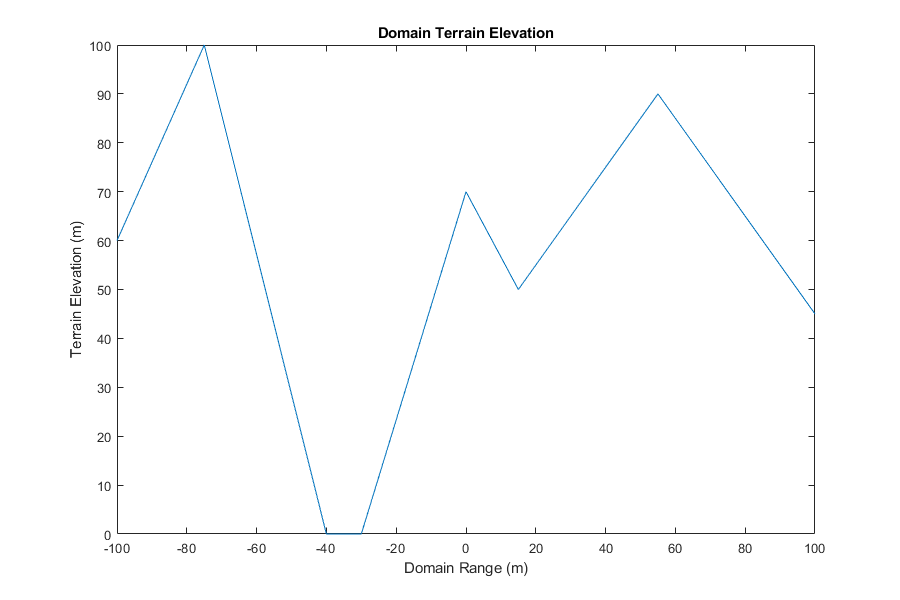

clear all

load("data (3).mat")
%let's put everything into a structure to make our life easier
data.time = z(:,1);
data.z.abs = z(:,2);
data.z.rel = z(:,3);
clear z %get rid of duplicate variables



%set up map domain
N = 1000; %use 1000 particles and why not let's use 1000 points in the domain
domain.range = [-100,100];
domain.x = -100:0.2:100;
domain.z = top_map(domain.x);
%plot the map
figure("Position",[10 10 900 600])
plot(domain.x,domain.z)
xlabel("Domain Range (m)")
ylabel("Terrain Elevation (m)")
title("Domain Terrain Elevation")

## Observation Model:

## The difference between the absolute measurement and the relative measurement gives the hieght of the terrain above sea level. The particles will have corresponding estimated terrain values based on their X-coordinate. The Innovation between the measurements and these estimated values is the innovation. The noise in the resulting observation will be gaussian where  $\sigma = v_{rel}+v_{abs}$.

## 
$$z_{abs} = \hat z +v_{abs}$$


## 
$$z_{rel} = \hat z +v_{rel}$$


## 
$$z_m = z_{abs}-z_{rel}$$


## $\mathbf{I} = z_m - \hat z$, where $\hat z = $top_map$(\hat x)$, if $isnan(\hat z)$ returns true $\hat z = 0$

# 2) Using the given initial belief above, implement a particle filter to localize the airplane. For this question, do not resample the particles. Plot the distribution of particles (with their corresponding weights) on the map from the previous question. Comment on the distribution of particles and weights. What is the effective number of particles at the end?

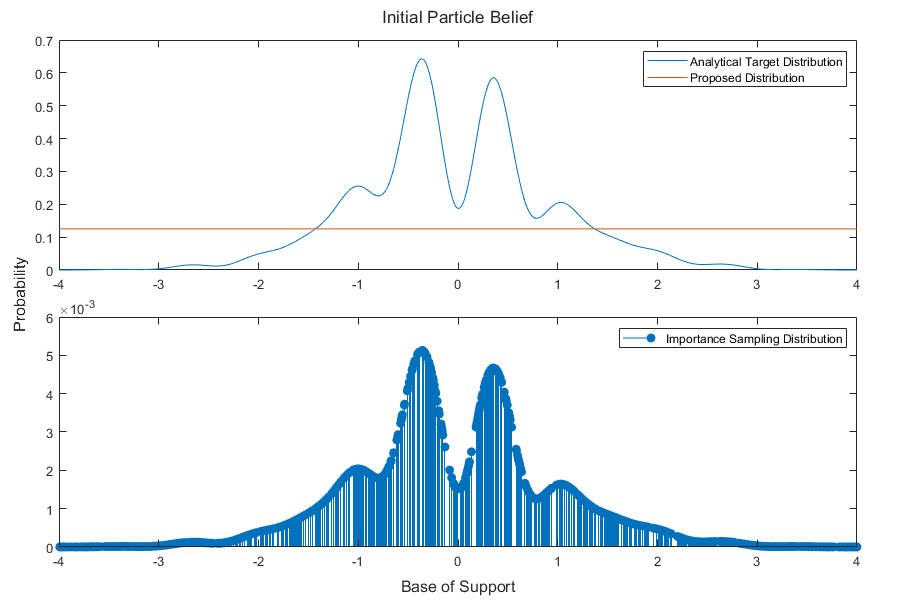

%setup PF
X = zeros([2,N]);
%analytical proposed
prop = 1/8*ones(1,N);
%sum(prop) %verifying uniform sol sums to 1
%generate a matrix of weights, row 1 is the domain location, row 2 is the
%weight value  
X(1,:) =-4 + (4+4)*rand(N,1);
for i = 1:N
    X(2,i) = 1/5.75*exp(-(X(1,i)^2)/2)*((sin(X(1,i)+6))^2+3*(cos(X(1,i)))^2*(sin(4*X(1,i)))^2+1);
    X(2,i) = X(2,i)/prop(i);
end
eta = sum(X(2,:));
X(2,:) = X(2,:)./eta;
%sum(X(2,:)) %verify sum to one
%analytical bel
num_x = linspace(-4,4,N);
bel = (1./5.75).*exp(-(num_x.^2)./2).*((sin(num_x+6)).^2+3.*(cos(num_x)).^2.*(sin(4.*num_x)).^2+1);
%a = cumtrapz(num_x,bel)
%a(end)


figure("Position",[10 10 900 600])
t=tiledlayout(2,1);
t.TileSpacing = 'compact';
t.Padding = 'compact';
ax1=nexttile;
plot(ax1,num_x,bel)
hold on
plot(ax1,num_x,prop)
hold off
legend(["Analytical Target Distribution","Proposed Distribution"])
%plot weights
ax2=nexttile;
stem(ax2,X(1,:),X(2,:),"filled")
xlabel(t,"Base of Support")
ylabel(t,"Probability")
title(t,"Initial Particle Belief")
legend(["Importance Sampling Distribution"])

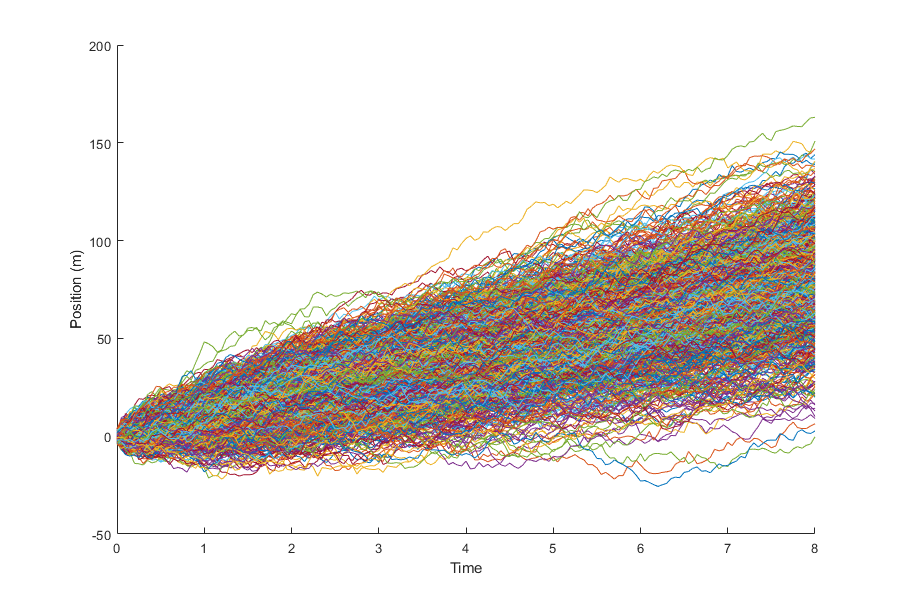

s0 = 10;
deltaT = 0.05;
t = 0:deltaT:8; % 8sec to match measruements???
mu = 0;
sigma = 2;
sigmaABS = 1.5;
sigmaInn = 2^2+2.5^2; %total noise
state = zeros(N,length(t));
state(:,1) = X(1,:); %put in initial particles
w = zeros(length(data.time),N);
w(1,:) = X(2,:); %initialize weights
xmeasure = zeros(N,length(data.time));
xmeasure(:,1) = X(1,:); %initialize domain for weight tracking
tol = eps(N); %precision for floating point
for i=1:length(t)
    wk = normrnd(mu,sigma,[N,1]); %generate a new noise vecotr
    state(:,i+1) = state(:,i)+s0*deltaT+wk;
    for j=1:length(data.time)
        T = abs(t(i)-data.time(j));
        if T < tol
            %do the measurement update
            xmeasure(:,j+1) = state(:,i+1); %put states where measurements happen into a sepperate var for visual purposes
            zhat = top_map(state(:,i+1)); %expected terain elevation
            for k=1:N
                %throwout NaNs
                if isnan(zhat(k))
                    zhat(k)=0;
                end
            end
            vABS = normrnd(mu,sigmaABS); 
            zABS = data.z.abs(j) + vABS;
            vREL = normrnd(mu,sigma);
            zREL = data.z.rel(j) + vREL;
            zM = zABS -zREL;
            Inn = zM - zhat;
            w(j+1,:) = normpdf(Inn,mu,sigmaInn); %compute weight
            w(j+1,:) = w(j+1,:).*w(j,:); %update weight
            w(j+1,:) = w(j+1,:)./sum(w(j+1,:)); %normalize weight
        end
    end
end
state(:,end)=[];
figure("Position",[10 10 900 600])
%plot trajectories from process model
hold on
for n=1:N
    plot(t,state(n,:))
end
hold off
xlabel("Time")
ylabel("Position (m)")

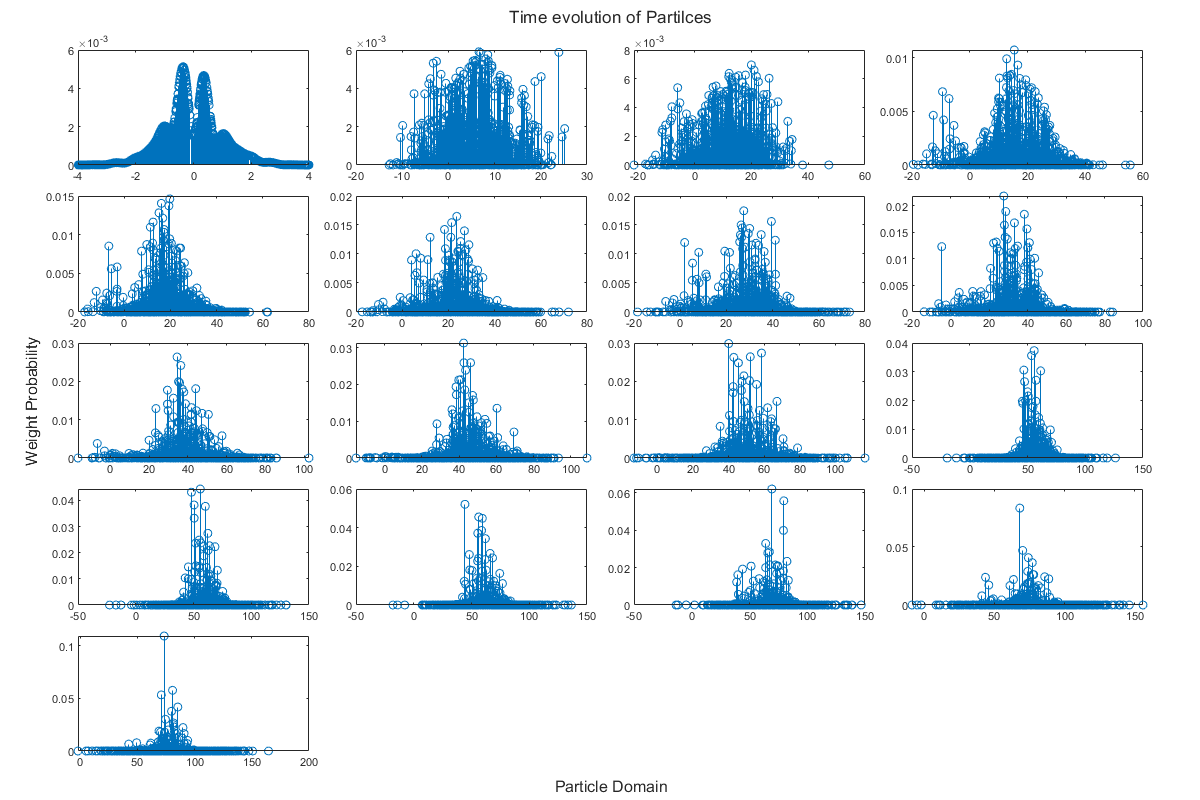

figure("Position",[10 10 1200 800])
t3 = tiledlayout(5,4);
t3.TileSpacing = "compact";
t3.Padding="compact";
for i=1:length(range(xmeasure))
    
    stem(nexttile(i),xmeasure(:,i),w(i,:));
end
xlabel(t3,"Particle Domain")
ylabel(t3,"Weight Probability")
title(t3,"Time evolution of Partilces")

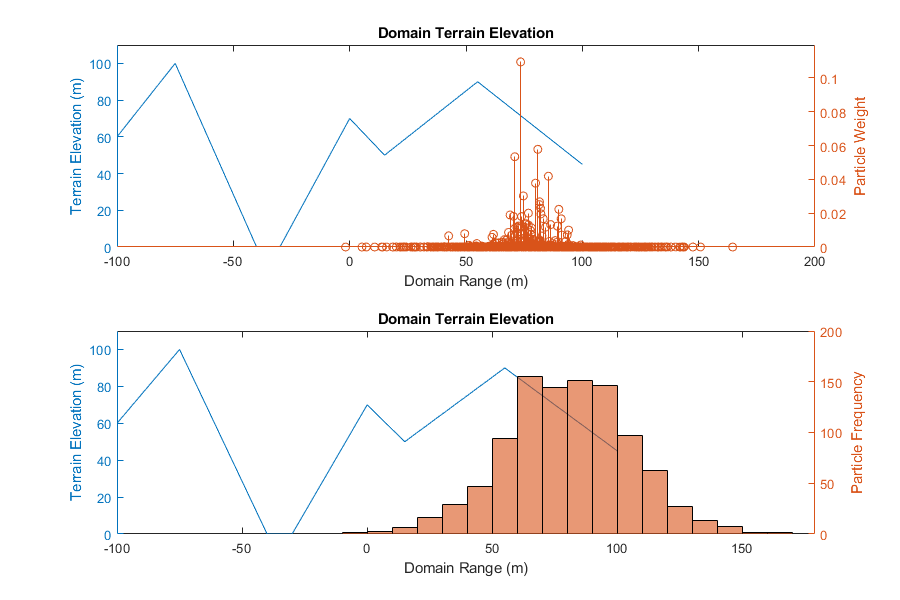

figure("Position",[10 10 900 600])
figure("Position",[10 10 900 600])
t4 = tiledlayout(2,1);
ax1 = nexttile;
yyaxis left
plot(ax1,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
stem(ax1,xmeasure(:,end),w(end,:))
hold off
xlabel("Domain Range (m)")
ylim([0 max(w(end,:))+0.01])
ylabel("Particle Weight")
title("Domain Terrain Elevation")
ax2 = nexttile;
yyaxis left
plot(ax2,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
h = histogram(ax2,xmeasure(:,end));
hold off
xlabel("Domain Range (m)")
ylabel("Particle Frequency")
title("Domain Terrain Elevation")

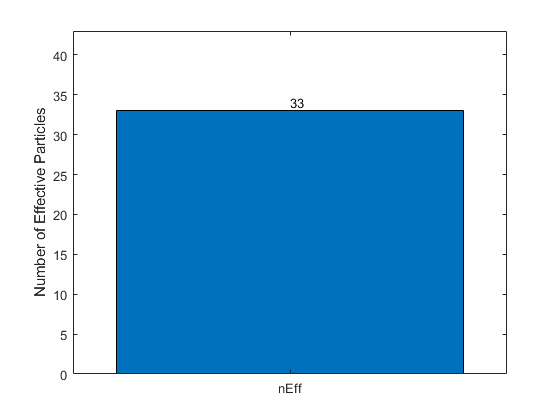

nEff = 0;
for i=1:N
    temp = w(end,i)^2;
    nEff = nEff+temp;
end
nEff = round(1/nEff);
figure
cat=categorical({'nEff'});
b = bar(cat,nEff);
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'VerticalAlignment',"bottom")
ylim([0 nEff+10])
ylabel('Number of Effective Particles')

## The effective number of particles is shown in the bar graph above (ranges between 20- 60 depending on the random seeding). 

# 3) Now, use the resampling alrogithm strategically by only resampling the particles when some threshold for the effective number of particles is crossed. How does the distribution of particles change as compared to that from the previous question?

## thresh < 65% effective particles left

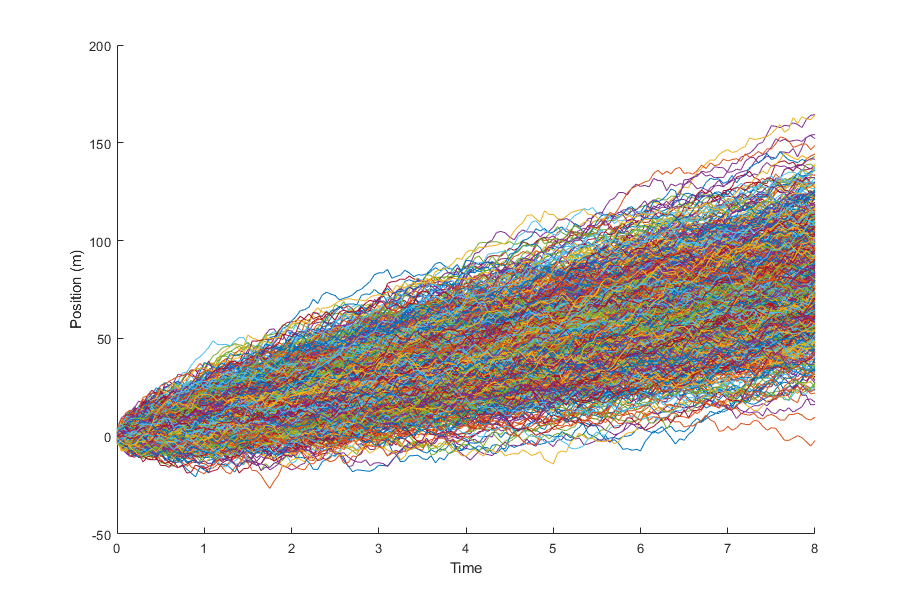

s0 = 10;
deltaT = 0.05;
t = 0:deltaT:8; % 8sec to match measruements???
mu = 0;
sigma = 2;
sigmaABS = 1.5;
sigmaInn = 2^2+2.5^2;
state = zeros(N,length(t));
state(:,1) = X(1,:); %put in initial particles
w = zeros(length(data.time),N);
w(1,:) = X(2,:); %initialize weights
xmeasure = zeros(N,length(data.time));
xmeasure(:,1) = X(1,:); %initialize domain for weight tracking
tol = eps(N); %precision for floating point
thresh = 0.65; % 65% threshold for resampling
for i=1:length(t)
    wk = normrnd(mu,sigma,[N,1]); %generate a new noise vecotr
    state(:,i+1) = state(:,i)+s0*deltaT+wk;
    for j=1:length(data.time)
        T = abs(t(i)-data.time(j));
        if T < tol
            %do the measurement update
            xmeasure(:,j+1) = state(:,i+1); %put states where measurements happen into a sepperate var for visual purposes
            zhat = top_map(state(:,i+1)); %expected terain elevation
            for k=1:N
                %throwout NaNs
                if isnan(zhat(k))
                    zhat(k)=0;
                end
            end
            vABS = normrnd(mu,sigmaABS); 
            zABS = data.z.abs(j) + vABS;
            vREL = normrnd(mu,sigma);
            zREL = data.z.rel(j) + vREL;
            zM = zABS -zREL;
            Inn = zM - zhat;
            w(j+1,:) = normpdf(Inn,mu,sigmaInn); %compute weight
            w(j+1,:) = w(j+1,:).*w(j,:); %update weight
            w(j+1,:) = w(j+1,:)./sum(w(j+1,:)); %normalize weight
            nEff = 0;
            for k=1:N
                temp = w(j+1,k)^2;
                nEff = nEff+temp;
            end
            %nEff; %checks to make sure it's working
            %temp = 1/nEff;
            nEff = round(1/nEff);
            if nEff/1000 < thresh
                [xmeasure(:,j+1),w(j+1,:)] = REEsample(N,w(j+1,:),xmeasure(:,j+1));
            end
        end
    end
end
state(:,end)=[];
figure("Position",[10 10 900 600])
%plot trajectories from process model
hold on
for n=1:N
    plot(t,state(n,:))
end
hold off
xlabel("Time")
ylabel("Position (m)")

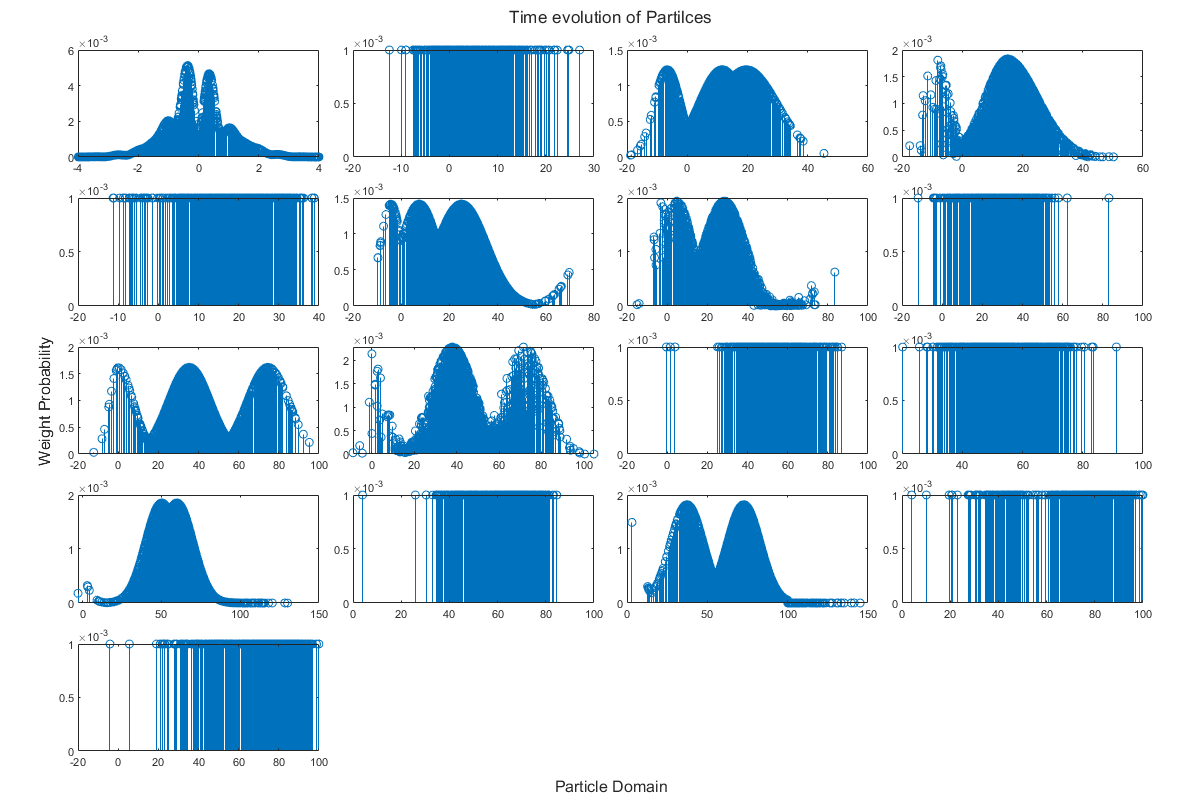


figure("Position",[10 10 1200 800])
t = tiledlayout(5,4);
t.TileSpacing = "compact";
t.Padding="compact";
for i=1:length(range(xmeasure))
    
    stem(nexttile(i),xmeasure(:,i),w(i,:));
end
xlabel(t,"Particle Domain")
ylabel(t,"Weight Probability")
title(t,"Time evolution of Partilces")

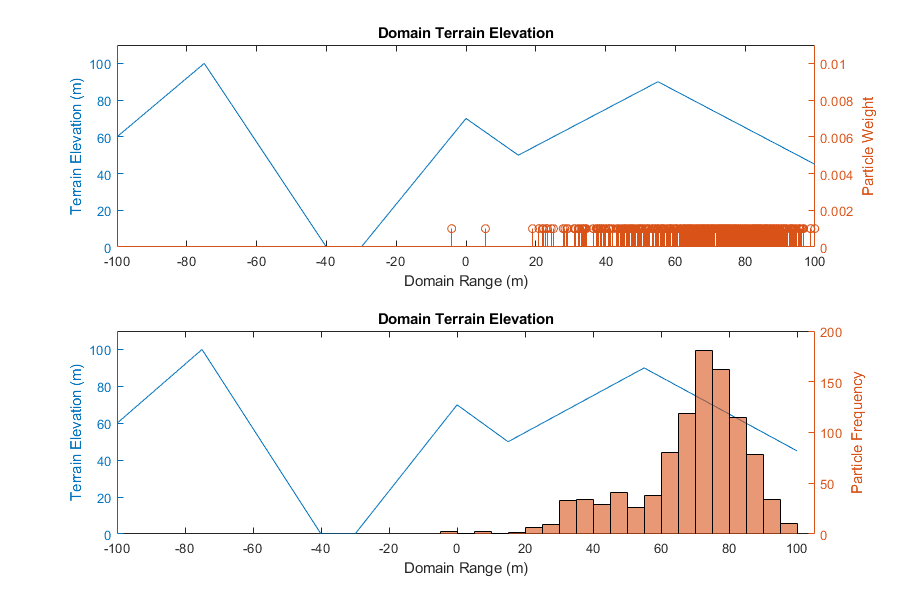


figure("Position",[10 10 900 600])
t2 = tiledlayout(2,1);
ax1 = nexttile;
yyaxis left
plot(ax1,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
stem(ax1,xmeasure(:,end),w(end,:))
hold off
xlabel("Domain Range (m)")
ylim([0 max(w(end,:))+0.01])
ylabel("Particle Weight")
title("Domain Terrain Elevation")
ax2 = nexttile;
yyaxis left
plot(ax2,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
h = histogram(ax2,xmeasure(:,end));
hold off
xlabel("Domain Range (m)")
ylabel("Particle Frequency")
title("Domain Terrain Elevation")

## Comments on distribution comparison to #2: 

## Significant improvement in the particle frequency for more likely hypothesis than in the non-resample case. While the distribution is slightly more spread out. If we were to sample once more we'd see that the highest frequency particles have the largest weights that exceed the previous case; this can be interpreted from the time series plot of particle weight evolution. Re-sampling is an excellent technique to use to improve particle filter efficiency. 

# 4) Now, use a uniform distribution whose base of support is the entire domain of the map as the initial belief for the particles. This represents the case when we have no idea where the airplane initially started in the map. (Note that your particle weights should sum to one). Implement your particles filter with strategic resampling from the previous question to localize the airplane. How does the distribution of particles and weights compare to those from the previous question? Also compare to the case when the particles are never resampled.

%setup PF
X = zeros([2,N]);
%analytical proposed
prop = 1/(100--100)*ones(1,N);
%generate a matrix of weights, row 1 is the domain location, row 2 is the
%weight value  
X(1,:) =-100 + (100+100)*rand(N,1);
for i = 1:N
    X(2,i) = prop(i);
    X(2,i) = X(2,i)/prop(i);
end
eta = sum(X(2,:));
X(2,:) = X(2,:)./eta;
sum(X(2,:)) %verify sum to one

ans = 1.0000

%analytical bel
num_x = linspace(-100,100,N);

figure("Position",[10 10 900 600])
t = tiledlayout(1,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


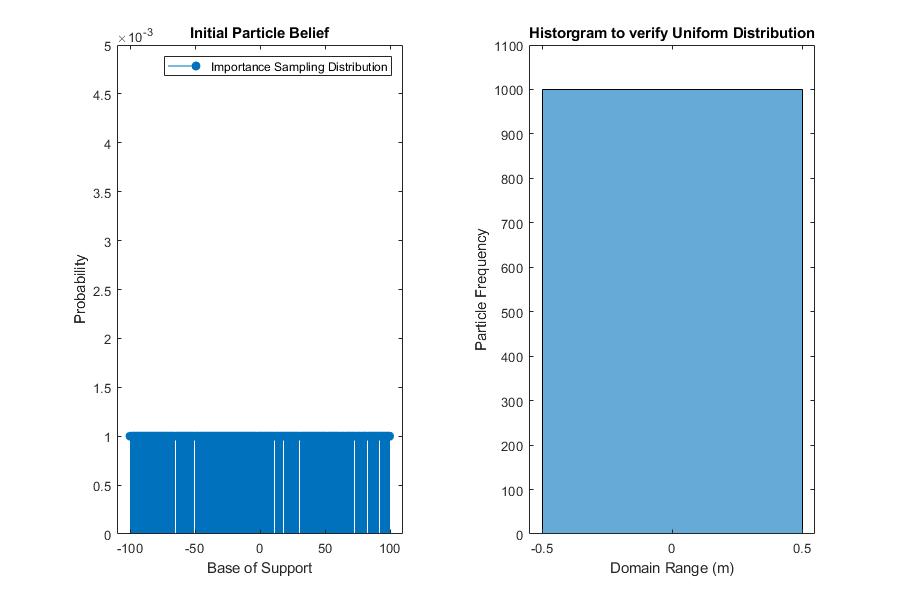

%plot weights
ax1 = nexttile;
stem(ax1,X(1,:),X(2,:),"filled")
xlabel("Base of Support")
ylabel("Probability")
title("Initial Particle Belief")
legend(["Importance Sampling Distribution"])
xlim([-110 110])
ylim([0 0.005])
ax2 = nexttile;
h = histogram(ax2,X(2,:));
xlabel("Domain Range (m)")
ylabel("Particle Frequency")
ylim([0 1100])
title("Historgram to verify Uniform Distribution")

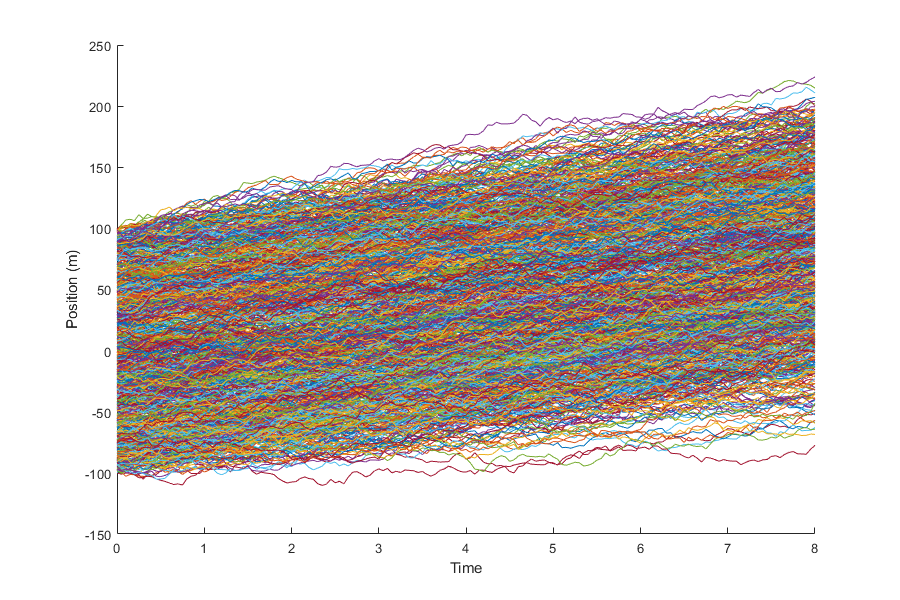

s0 = 10;
deltaT = 0.05;
t = 0:deltaT:8; % 8sec to match measruements???
mu = 0;
sigma = 2;
sigmaABS = 1.5;
sigmaInn = 2^2+2.5^2;
state = zeros(N,length(t));
state(:,1) = X(1,:); %put in initial particles
w = zeros(length(data.time),N);
w(1,:) = X(2,:); %initialize weights
xmeasure = zeros(N,length(data.time));
xmeasure(:,1) = X(1,:); %initialize domain for weight tracking
tol = eps(N); %precision for floating point
thresh = 0.75; % 75% threshold for resampling
for i=1:length(t)
    wk = normrnd(mu,sigma,[N,1]); %generate a new noise vecotr
    state(:,i+1) = state(:,i)+s0*deltaT+wk;
    for j=1:length(data.time)
        T = abs(t(i)-data.time(j));
        if T < tol
            %do the measurement update
            xmeasure(:,j+1) = state(:,i+1); %put states where measurements happen into a sepperate var for visual purposes
            zhat = top_map(state(:,i+1)); %expected terain elevation
            for k=1:N
                %throwout NaNs
                if isnan(zhat(k))
                    zhat(k)=0;
                end
            end
            vABS = normrnd(mu,sigmaABS); 
            zABS = data.z.abs(j) + vABS;
            vREL = normrnd(mu,sigma);
            zREL = data.z.rel(j) + vREL;
            zM = zABS -zREL;
            Inn = zM - zhat;
            w(j+1,:) = normpdf(Inn,mu,sigmaInn); %compute weight
            w(j+1,:) = w(j+1,:).*w(j,:); %update weight
            w(j+1,:) = w(j+1,:)./sum(w(j+1,:)); %normalize weight
            nEff = 0;
            for k=1:N
                temp = w(j+1,k)^2;
                nEff = nEff+temp;
            end
            %nEff; %checks to make sure it's working
            %temp = 1/nEff;
            nEff = round(1/nEff);
            if nEff/1000 < thresh
                [xmeasure(:,j+1),w(j+1,:)] = REEsample(N,w(j+1,:),xmeasure(:,j+1));
            end
        end
    end
end
state(:,end)=[];
figure("Position",[10 10 900 600])
%plot trajectories from process model
hold on
for n=1:N
    plot(t,state(n,:))
end
hold off
xlabel("Time")
ylabel("Position (m)")

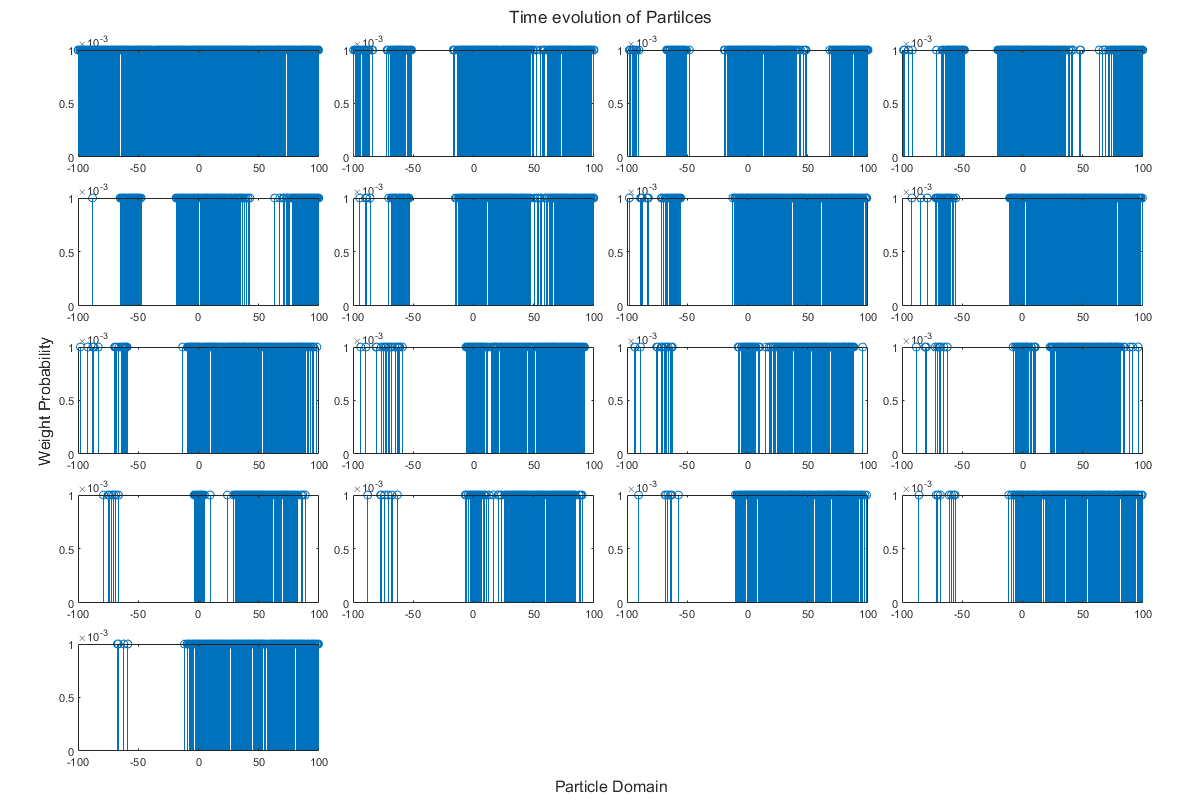

figure("Position",[10 10 1200 800])
t = tiledlayout(5,4);
t.TileSpacing = "compact";
t.Padding="compact";
for i=1:length(range(xmeasure))
    
    stem(nexttile(i),xmeasure(:,i),w(i,:));
end
xlabel(t,"Particle Domain")
ylabel(t,"Weight Probability")
title(t,"Time evolution of Partilces")

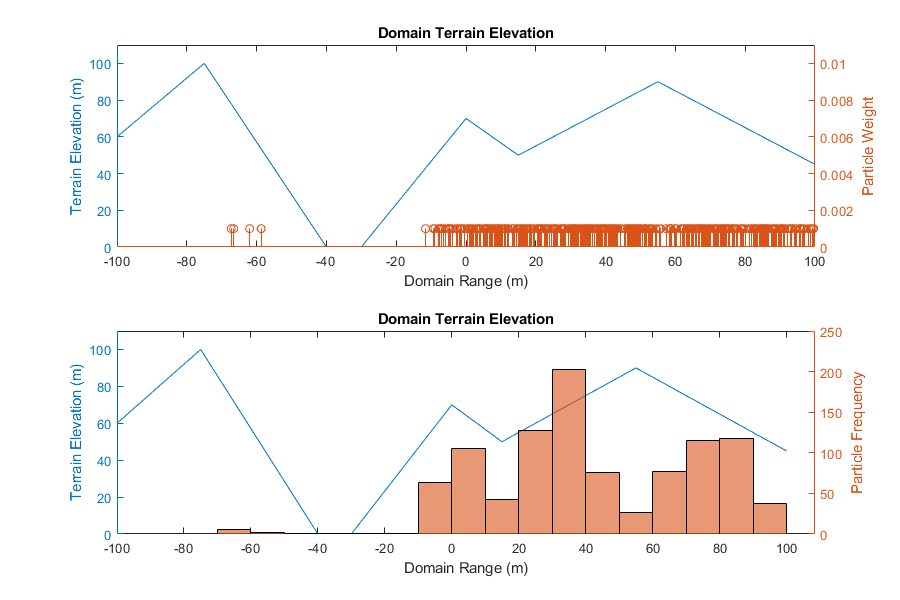

figure("Position",[10 10 900 600])
t2 = tiledlayout(2,1);
ax1 = nexttile;
yyaxis left
plot(ax1,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
stem(ax1,xmeasure(:,end),w(end,:))
hold off
xlabel("Domain Range (m)")
ylim([0 max(w(end,:))+0.01])
ylabel("Particle Weight")
title("Domain Terrain Elevation")
ax2 = nexttile;
yyaxis left
plot(ax2,domain.x,domain.z)
ylabel("Terrain Elevation (m)")
ylim([0 110])
hold on
yyaxis right
h = histogram(ax2,xmeasure(:,end));
hold off
xlabel("Domain Range (m)")
ylabel("Particle Frequency")
title("Domain Terrain Elevation")

## Comments:

## Distribution of particle weights is much more spread out than in the previous cases where our belief was that the particels were somewhere between -4 and 4 initially. However, we still end up with results mostly in the postitve side of the domain as we should expect. The actual particle weights are also significantly lower than either of the previous two cases since we keep so many more different particle hypothesis. More frequent measurement updates could help to improve the uncertainty, or a direct position measurement that doesn't rely on relative and absolute altitudes. 